# LIDAR Functions

 Mahdi, 3/8/2023, Personal Revision 

clc       % clear command window
clear     % clear MATLAB workspace

### Set Up Lidar

disp("program running"); % indicate lidar code starts ok

program running


warning('off', 'all'); % temporarily turn matlab warnings off. The code is a bit wonky
% so it will throw errors when you run the program

% there might be old objects in the lidar serial object so we need to find
% it and delete to prevent any conflicts
serialObjs = instrfind; % reads serial port objects 
if ~isempty(serialObjs) % a conditional to check if there are any old objects
    fclose(serialObjs); % closes the serial port connected to old Lidar
    delete(serialObjs); % delete the old lidar objects
end

%clearing any old objects to avoid conflicts
clear
clc

**Specifiying the USB serial port that the Hokuyo Lidar is plugged into**

comPort = "COM4"; % COM port that the lidar is connected to (from windows settings) 
disp("Com Port Set")

Com Port Set


### Connect to Lidar and setting serial communication parameters

disp("connecting to lidarand setting Lidar parameters");

connecting to lidarand setting Lidar parameters


disp("expect a short delay while setting...");

expect a short delay while setting...



lidar = serial(comPort, 'baudrate', 115200); % creatig a serial port object called lidar 
set(lidar, 'Timeout', 2); % setting communication link timeout
set(lidar, 'InputBufferSize', 200000); % setting data input buffer size
set(lidar, 'Terminator', 'LF/CR'); % setting data stream terminator for fprintf and fscanf

% serial communications complexity for devices are driven by the
% manufacturer. In this case we are setting Hokuyo parameters to configure Lidar 
fopen(lidar); % connects Lidar or the serial port object 
pause(0.3); % pause for command transmission
fprintf(lidar, 'SCIP2.0'); % writes a string cmd to lidar
pause(0.3); % pause for the command to be sent
fscanf(lidar); % reads ASCII data from the device connected to Lidar
fprintf(lidar, 'W');
pause(0.3);
fscanf(lidar);
fprintf(lidar,'BW');
pause(0.3);
fscanf(lidar);
fprintf(lidar, 'MD0044072500');
pause(0.3);
fscanf(lidar);
clc
disp("Lidar set")

Lidar set


% in the code above, we essentially create the serial port object (lidar)
% and configure it to allow serial communication with Hokuyo through the
% USB port. In the second chunk of the code, we open that communication
% link and tell (send it coded texts) the Hokuyo lidar to send us back a
% set of range data

### Inititalize Lidar display figure Window

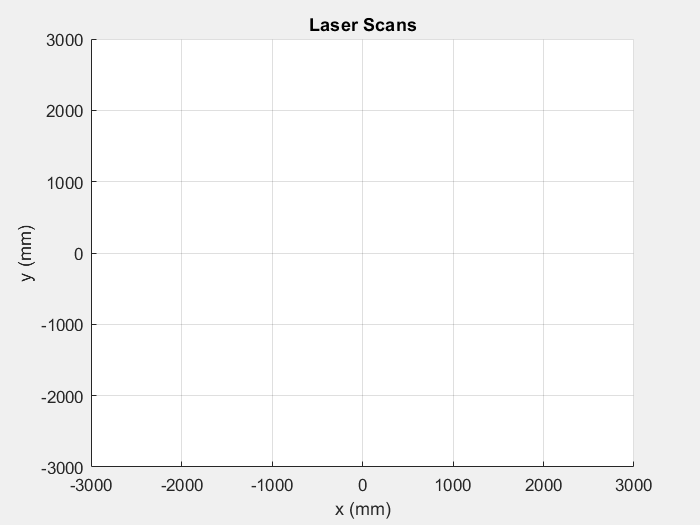

% here, we are creating a stand-alone figure window that will be used to
% plot once we get the Lidar data 
LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle', 'off', ...
    'MenuBar', 'figure', 'units', 'normalized', 'Visible', 'on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'units', 'normalized', 'NextPlot', ...
    'replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String='Laser Scans';
LaserPlot1.axis1.XLabel.String='X Axis';
LaserPlot1.axis1.YLabel.String='Y Axis';

% we create a primitive line object which is a matlab synatax that plots a line
% based on x and y data. In this case our x and y data is XData and YData
% respectively and both of them are empty vectors waiting to be filled with
% Lidar data
laserRange = line('Parent', LaserPlot1.axis1, 'XData', [], 'YData', [], 'LineStyle', ...
    'none', 'marker', '.', 'color', 'b', 'LineWidth', 2);
grid on
axis([-3000 3000 -3000 3000])
xlabel('x (mm)')
ylabel('y (mm)')

disp("Laser Scans figure set");

Laser Scans figure set


### Sample and Visualize Data

This code's main task is to read lidar range data over serial link and plot it to a figure

disp("Read and Plot Lidar Data, type and hold cntrl-c to stop")

Read and Plot Lidar Data, type and hold cntrl-c to stop


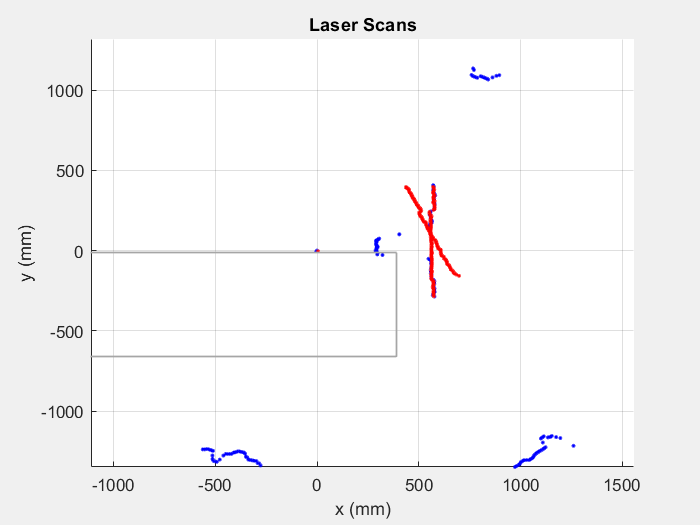

 
angles = (-120:240/682:120-240/682)*pi/180; % convert sensor steps (distances) to angles
tStart = tic; % start experiment time using the tic function 
iscan = 1;
while (iscan == 1) % this loop continous for 60 seconds 
    [A] = FunRoboLidarScan(lidar); % lidar scan range data is stored in [A]
    laserRange.XData = A .* cos(angles); % finding the x coordinate using trig
    laserRange.YData = A .* sin(angles); % finding the y coordinate using trig

    drawnow % draws laserRange in the Laser Scan window 
    pause(0.2) % pausing for serial communication to keep up
    tElapsed = toc(tStart); % returns time elapsed since the tic function was triggered
    if (tElapsed > 60) % condition checks to make sure the experiment doesn't run for 
                       % longer than 60 seconds
        iscan = 0;     % will break the loop by setting iscan variable to 0 once 
                       % the condition is met
    end
end 


disp("Laser scan ended");

Run this code first with no objects infront of the wall 

% capture the laser x and y coordinate readings for the wall with no
% objects infront on x1 and y1 and save the data on wallonlydata.mat
x1 = [laserRange.XData]

x1 = 1.0e+03 *

   -0.5895   -0.5847   -0.5828   -0.5769   -0.5733   -0.5716   -0.5870   -0.5802   -0.5734   -0.5629   -0.5547   -0.5461   -0.5353   -0.5242   -0.5047   -0.4964   -0.4898   -0.4831   -0.4765   -0.4710   -0.4662   -0.4602   -0.4553   -0.4529   -0.4467   -0.4401   -0.4364   -0.4293   -0.4236   -0.4165   -0.4094   -0.4023   -0.3955   -0.3883   -0.3824   -0.3757   -0.3733   -0.3773   -0.3800   -0.3722   -0.3753   -0.3678   -0.3607   -0.3515   -0.3444   -0.3362   -0.3292   -0.3240   -0.3157   -0.3074


y1 = [laserRange.YData]

y1 = 1.0e+03 *

   -1.0210   -1.0273   -1.0387   -1.0431   -1.0519   -1.0642   -1.1092   -1.1128   -1.1164   -1.1127   -1.1135   -1.1133   -1.1085   -1.1027   -1.0788   -1.0782   -1.0812   -1.0842   -1.0872   -1.0928   -1.1003   -1.1050   -1.1124   -1.1263   -1.1310   -1.1346   -1.1457   -1.1484   -1.1547   -1.1573   -1.1599   -1.1624   -1.1657   -1.1682   -1.1743   -1.1786   -1.1961   -1.2357   -1.2725   -1.2748   -1.3155   -1.3197   -1.3258   -1.3241   -1.3301   -1.3322   -1.3391   -1.3538   -1.3557   -1.3576


save('wallonlydata','x1','y1')

This code plots the data for wall without obstacles in front

% set x and y limits to take the data we only need and disregard the rest
x1highestlim = 700

x1highestlim = 700

x1lowestlim = 0

x1lowestlim = 0

y1highestlim = 400

y1highestlim = 400

y1lowestlim = -400

y1lowestlim = -400


% creating a matrix of x1 and y1 and apply the limits
combinedata = [x1;y1]

combinedata = 1.0e+03 *

   -0.5895   -0.5847   -0.5828   -0.5769   -0.5733   -0.5716   -0.5870   -0.5802   -0.5734   -0.5629   -0.5547   -0.5461   -0.5353   -0.5242   -0.5047   -0.4964   -0.4898   -0.4831   -0.4765   -0.4710   -0.4662   -0.4602   -0.4553   -0.4529   -0.4467   -0.4401   -0.4364   -0.4293   -0.4236   -0.4165   -0.4094   -0.4023   -0.3955   -0.3883   -0.3824   -0.3757   -0.3733   -0.3773   -0.3800   -0.3722   -0.3753   -0.3678   -0.3607   -0.3515   -0.3444   -0.3362   -0.3292   -0.3240   -0.3157   -0.3074
   -1.0210   -1.0273   -1.0387   -1.0431   -1.0519   -1.0642   -1.1092   -1.1128   -1.1164   -1.1127   -1.1135   -1.1133   -1.1085   -1.1027   -1.0788   -1.0782   -1.0812   -1.0842   -1.0872   -1.0928   -1.1003   -1.1050   -1.1124   -1.1263   -1.1310   -1.1346   -1.1457   -1.1484   -1.1547   -1.1573   -1.1599   -1.1624   -1.1657   -1.1682   -1.1743   -1.1786   -1.1961   -1.2357   -1.2725   -1.2748   -1.3155   -1.3197   -1.3258   -1.3241   -1.3301   -1.3322   -1.3391   -

combinedata = combinedata(:,combinedata(1,:)>x1lowestlim) 

combinedata = 1.0e+03 *

    0.0096    0.0224    0.0353    0.0485    0.0618    0.0748    0.0879    0.1009    0.1140    0.1516    0.1672    0.1835    0.1991    0.2153    0.2318    0.2478    0.2637    0.2802    0.2966    0.3144    0.3319    0.3478    0.3636    0.3695    0.3839    0.3993    0.4146    0.4313    0.4971    0.5142    0.5313    0.5476    0.5630    0.5798    0.5950    0.6103    0.6249    0.6397    0.6554    0.6717    0.6841    0.6985    0.7146    0.7298    0.7436    0.7593    0.7734    0.7889    0.8035    0.8170
   -2.0860   -2.0859   -2.0887   -2.1044   -2.1161   -2.1177   -2.1192   -2.1186   -2.1189   -2.5285   -2.5285   -2.5384   -2.5372   -2.5439   -2.5515   -2.5540   -2.5544   -2.5597   -2.5639   -2.5789   -2.5898   -2.5877   -2.5856   -2.5150   -2.5058   -2.5034   -2.5009   -2.5062   -2.7860   -2.7829   -2.7797   -2.7724   -2.7612   -2.7567   -2.7453   -2.7347   -2.7212   -2.7095   -2.7016   -2.6966   -2.6759   -2.6640   -2.6586   -2.6504   -2.6372   -2.6306   -2.6192   -

combinedata = combinedata(:,combinedata(1,:)<x1highestlim)

combinedata = 1.0e+03 *

    0.0096    0.0224    0.0353    0.0485    0.0618    0.0748    0.0879    0.1009    0.1140    0.1516    0.1672    0.1835    0.1991    0.2153    0.2318    0.2478    0.2637    0.2802    0.2966    0.3144    0.3319    0.3478    0.3636    0.3695    0.3839    0.3993    0.4146    0.4313    0.4971    0.5142    0.5313    0.5476    0.5630    0.5798    0.5950    0.6103    0.6249    0.6397    0.6554    0.6717    0.6841    0.6985    0.0054    0.5733    0.5723    0.5722    0.5730    0.5738    0.5718    0.5715
   -2.0860   -2.0859   -2.0887   -2.1044   -2.1161   -2.1177   -2.1192   -2.1186   -2.1189   -2.5285   -2.5285   -2.5384   -2.5372   -2.5439   -2.5515   -2.5540   -2.5544   -2.5597   -2.5639   -2.5789   -2.5898   -2.5877   -2.5856   -2.5150   -2.5058   -2.5034   -2.5009   -2.5062   -2.7860   -2.7829   -2.7797   -2.7724   -2.7612   -2.7567   -2.7453   -2.7347   -2.7212   -2.7095   -2.7016   -2.6966   -2.6759   -2.6640   -0.0045   -0.2845   -0.2797   -0.2753   -0.2713   -

combinedata = combinedata(:,combinedata(2,:)>y1lowestlim)

combinedata =     5.3807  573.2905  572.3316  572.2360  573.0121  573.7613  571.7566  571.5330  572.1918  573.7405  572.5107  573.0875  573.6379  571.3838  568.1612  569.5475  569.9794  570.3855  573.5773  572.9986  572.3900  570.8079  572.0287  573.2278  570.6076  566.0478  562.3971  562.5269  560.7180  561.7532  562.7672  562.7980  561.8404  559.8897  559.8422  561.7073  562.5843  563.4401  564.2746  565.0879  561.9772  559.8115  560.5516  561.2707  561.9685  562.6451  562.3175  561.9664  563.5624  563.1667
   -4.4775 -284.4961 -279.6526 -275.2652 -271.3174 -267.3705 -262.1743 -257.8352 -253.9145 -250.3953 -245.6837 -241.7741 -237.8666 -232.8295 -227.4574 -223.9636 -220.1010 -216.2416 -213.4318 -209.2189 -205.0213 -200.5076 -196.9980 -193.4810 -188.7007 -183.3437 -178.3522 -174.5982 -170.2683 -166.8212 -163.3678 -159.6354 -155.6418 -151.4050 -147.7083 -144.5161 -141.0635 -137.6055 -134.1423 -130.6741 -126.3237 -122.2297 -118.7891 -115.3441 -111.8946 -108.4410 -104.8000 -101.1672  -97

combinedata = combinedata(:,combinedata(2,:)<y1highestlim)

combinedata =     5.3807  573.2905  572.3316  572.2360  573.0121  573.7613  571.7566  571.5330  572.1918  573.7405  572.5107  573.0875  573.6379  571.3838  568.1612  569.5475  569.9794  570.3855  573.5773  572.9986  572.3900  570.8079  572.0287  573.2278  570.6076  566.0478  562.3971  562.5269  560.7180  561.7532  562.7672  562.7980  561.8404  559.8897  559.8422  561.7073  562.5843  563.4401  564.2746  565.0879  561.9772  559.8115  560.5516  561.2707  561.9685  562.6451  562.3175  561.9664  563.5624  563.1667
   -4.4775 -284.4961 -279.6526 -275.2652 -271.3174 -267.3705 -262.1743 -257.8352 -253.9145 -250.3953 -245.6837 -241.7741 -237.8666 -232.8295 -227.4574 -223.9636 -220.1010 -216.2416 -213.4318 -209.2189 -205.0213 -200.5076 -196.9980 -193.4810 -188.7007 -183.3437 -178.3522 -174.5982 -170.2683 -166.8212 -163.3678 -159.6354 -155.6418 -151.4050 -147.7083 -144.5161 -141.0635 -137.6055 -134.1423 -130.6741 -126.3237 -122.2297 -118.7891 -115.3441 -111.8946 -108.4410 -104.8000 -101.1672  -97

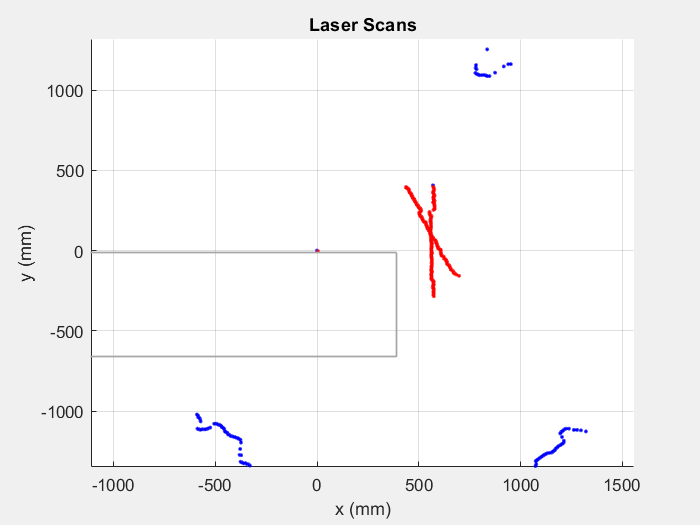


% plots on the previous diagram 
hold on
wallplot = line('Parent', LaserPlot1.axis1, 'XData', combinedata(1,:), 'YData', combinedata(2,:), 'LineStyle', ...
    'none', 'marker', '.', 'color', 'r', 'LineWidth', 2);

Run this code after placing an object infront of the wall 

% new x and y data with obstacles infront of the wall
x2 = [laserRange.XData]

x2 = 1.0e+03 *

         0         0         0         0         0         0         0         0         0   -0.0032         0         0   -0.0030         0         0         0   -0.5612   -0.5519   -0.5419   -0.5335   -0.5259   -0.5182   -0.5106   -0.5134   -0.5129   -0.5081   -0.5001   -0.4920   -0.4777   -0.4595   -0.4470   -0.4386   -0.4298   -0.4211   -0.4099   -0.4007   -0.3905   -0.3820   -0.3743   -0.3666   -0.3589   -0.3527   -0.3494   -0.3420   -0.3371   -0.3291   -0.3211   -0.3131   -0.3050   -0.2970


y2 = [laserRange.YData]

y2 = 1.0e+03 *

         0         0         0         0         0         0         0         0         0   -0.0062         0         0   -0.0063         0         0         0   -1.2388   -1.2386   -1.2365   -1.2379   -1.2412   -1.2444   -1.2476   -1.2766   -1.2984   -1.3099   -1.3130   -1.3160   -1.3021   -1.2768   -1.2664   -1.2672   -1.2671   -1.2668   -1.2589   -1.2567   -1.2515   -1.2510   -1.2533   -1.2556   -1.2578   -1.2658   -1.2843   -1.2884   -1.3021   -1.3041   -1.3061   -1.3081   -1.3100   -1.3118


combinedata2 = [x2;y2]

combinedata2 = 1.0e+03 *

         0         0         0         0         0         0         0         0         0   -0.0032         0         0   -0.0030         0         0         0   -0.5612   -0.5519   -0.5419   -0.5335   -0.5259   -0.5182   -0.5106   -0.5134   -0.5129   -0.5081   -0.5001   -0.4920   -0.4777   -0.4595   -0.4470   -0.4386   -0.4298   -0.4211   -0.4099   -0.4007   -0.3905   -0.3820   -0.3743   -0.3666   -0.3589   -0.3527   -0.3494   -0.3420   -0.3371   -0.3291   -0.3211   -0.3131   -0.3050   -0.2970
         0         0         0         0         0         0         0         0         0   -0.0062         0         0   -0.0063         0         0         0   -1.2388   -1.2386   -1.2365   -1.2379   -1.2412   -1.2444   -1.2476   -1.2766   -1.2984   -1.3099   -1.3130   -1.3160   -1.3021   -1.2768   -1.2664   -1.2672   -1.2671   -1.2668   -1.2589   -1.2567   -1.2515   -1.2510   -1.2533   -1.2556   -1.2578   -1.2658   -1.2843   -1.2884   -1.3021   -1.3041   -1.3061   

x2highestlim = 700

x2lowestlim = 0

y2highestlim = 400

y2lowestlim = -400

% creating a matrix of x2 and y2 and apply the limits
combinedata2 = combinedata2(:,combinedata2(1,:)>x2lowestlim)

combinedata2 = 1.0e+03 *

    0.0099    0.0231    0.0364    0.0496    0.0628    0.0762    0.0912    0.1055    0.1198    0.1344    0.1482    0.1622    0.1760    0.1874    0.1993    0.2121    0.2255    0.2385    0.2508    0.2642    0.2775    0.2909    0.3042    0.3177    0.3312    0.3448    0.3611    0.3767    0.3942    0.4078    0.4213    0.4269    0.4401    0.4534    0.4687    0.4931    0.6233    0.6400    0.6566    0.6701    0.6853    0.7015    0.7159    0.7309    0.7472    0.7623    0.7734    0.7881    0.8014    0.8173
   -2.1530   -2.1529   -2.1527   -2.1524   -2.1521   -2.1577   -2.1991   -2.2155   -2.2268   -2.2420   -2.2411   -2.2441   -2.2431   -2.2141   -2.1940   -2.1857   -2.1844   -2.1790   -2.1685   -2.1670   -2.1653   -2.1645   -2.1627   -2.1628   -2.1618   -2.1617   -2.1783   -2.1888   -2.2091   -2.2066   -2.2041   -2.1612   -2.1586   -2.1558   -2.1628   -2.2096   -2.7144   -2.7105   -2.7065   -2.6898   -2.6808   -2.6756   -2.6635   -2.6542   -2.6497   -2.6412   -2.6192   

combinedata2 = combinedata2(:,combinedata2(1,:)<x2highestlim)

combinedata2 = 1.0e+03 *

    0.0099    0.0231    0.0364    0.0496    0.0628    0.0762    0.0912    0.1055    0.1198    0.1344    0.1482    0.1622    0.1760    0.1874    0.1993    0.2121    0.2255    0.2385    0.2508    0.2642    0.2775    0.2909    0.3042    0.3177    0.3312    0.3448    0.3611    0.3767    0.3942    0.4078    0.4213    0.4269    0.4401    0.4534    0.4687    0.4931    0.6233    0.6400    0.6566    0.6701    0.6853    0.5769    0.5687    0.5695    0.5712    0.5729    0.5745    0.5761    0.5777    0.5747
   -2.1530   -2.1529   -2.1527   -2.1524   -2.1521   -2.1577   -2.1991   -2.2155   -2.2268   -2.2420   -2.2411   -2.2441   -2.2431   -2.2141   -2.1940   -2.1857   -2.1844   -2.1790   -2.1685   -2.1670   -2.1653   -2.1645   -2.1627   -2.1628   -2.1618   -2.1617   -2.1783   -2.1888   -2.2091   -2.2066   -2.2041   -2.1612   -2.1586   -2.1558   -2.1628   -2.2096   -2.7144   -2.7105   -2.7065   -2.6898   -2.6808   -0.2863   -0.2779   -0.2740   -0.2705   -0.2669   -0.2634   

combinedata2 = combinedata2(:,combinedata2(2,:)>y2lowestlim)

combinedata2 =   576.8735  568.7376  569.5326  571.2045  572.8549  574.4836  576.0907  577.6761  574.6570  575.2676  575.8516  576.4091  576.9402  572.8030  572.3394  570.9123  572.2556  573.5773  574.8773  576.1557  572.6949  573.9197  575.1228  576.3042  573.6585  570.0228  560.6167  560.7180  560.7946  560.8465  559.9118  560.8767  561.8204  562.7429  561.7073  558.7044  559.5543  560.3831  561.1907  561.9772  558.8345  558.5951  560.2911  560.9878  560.6813  560.3513  562.9506  563.5624  562.1804  562.7477
 -286.2742 -277.8965 -273.9647 -270.4615 -266.9481 -263.4247 -259.8913 -256.3481 -250.7953 -246.8668 -242.9402 -239.0157 -235.0936 -229.3157 -225.0614 -220.4612 -216.9506 -213.4318 -209.9049 -206.3701 -201.1705 -197.6492 -194.1206 -190.5846 -185.8088 -180.7705 -174.0053 -170.2683 -166.5365 -162.8102 -158.8168 -155.3749 -151.9271 -148.4736 -144.5161 -140.0906 -136.6565 -133.2172 -129.7729 -126.3237 -122.0164 -118.3745 -115.1428 -111.6993 -108.0625 -104.4336 -101.3443  -97.8848  -9

combinedata2 = combinedata2(:,combinedata2(2,:)<y2highestlim)

combinedata2 =   576.8735  568.7376  569.5326  571.2045  572.8549  574.4836  576.0907  577.6761  574.6570  575.2676  575.8516  576.4091  576.9402  572.8030  572.3394  570.9123  572.2556  573.5773  574.8773  576.1557  572.6949  573.9197  575.1228  576.3042  573.6585  570.0228  560.6167  560.7180  560.7946  560.8465  559.9118  560.8767  561.8204  562.7429  561.7073  558.7044  559.5543  560.3831  561.1907  561.9772  558.8345  558.5951  560.2911  560.9878  560.6813  560.3513  562.9506  563.5624  562.1804  562.7477
 -286.2742 -277.8965 -273.9647 -270.4615 -266.9481 -263.4247 -259.8913 -256.3481 -250.7953 -246.8668 -242.9402 -239.0157 -235.0936 -229.3157 -225.0614 -220.4612 -216.9506 -213.4318 -209.9049 -206.3701 -201.1705 -197.6492 -194.1206 -190.5846 -185.8088 -180.7705 -174.0053 -170.2683 -166.5365 -162.8102 -158.8168 -155.3749 -151.9271 -148.4736 -144.5161 -140.0906 -136.6565 -133.2172 -129.7729 -126.3237 -122.0164 -118.3745 -115.1428 -111.6993 -108.0625 -104.4336 -101.3443  -97.8848  -9

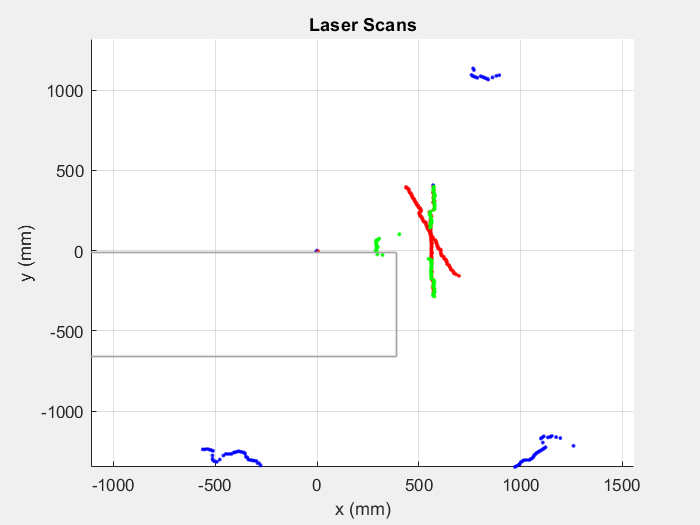


% plots again on the same plot
hold on
wallplot = line('Parent', LaserPlot1.axis1, 'XData', combinedata2(1,:), 'YData', ...
combinedata2(2,:), 'LineStyle','none', 'marker', '.', 'color', 'g', 'LineWidth', 2);


% we subtract the two combinedata matrices to get the values of the object
% (minus the wall coordinates)
mask = combinedata - combinedata2

mask =  -571.4929    4.5528    2.7990    1.0316    0.1572   -0.7223   -4.3341   -6.1430   -2.4652   -1.5271   -3.3409   -3.3216   -3.3023   -1.4192   -4.1782   -1.3648   -2.2761   -3.1918   -1.3001   -3.1571   -0.3049   -3.1117   -3.0941   -3.0764   -3.0509   -3.9750    1.7804    1.8088   -0.0766    0.9067    2.8554    1.9213    0.0200   -2.8532   -1.8651    3.0029    3.0300    3.0570    3.0839    3.1107    3.1427    1.2164    0.2605    0.2829    1.2872    2.2938   -0.6331   -1.5960    1.3820    0.4190
  281.7967   -6.5996   -5.6879   -4.8036   -4.3693   -3.9458   -2.2829   -1.4871   -3.1191   -3.5286   -2.7435   -2.7583   -2.7730   -3.5138   -2.3960   -3.5023   -3.1504   -2.8098   -3.5269   -2.8488   -3.8508   -2.8584   -2.8774   -2.8964   -2.8919   -2.5732   -4.3468   -4.3299   -3.7318   -4.0109   -4.5511   -4.2606   -3.7147   -2.9314   -3.1921   -4.4255   -4.4070   -4.3883   -4.3694   -4.3504   -4.3072   -3.8552   -3.6464   -3.6447   -3.8322   -4.0074   -3.4557   -3.2823   -3.7933  

object = zeros(1,200); 

% iterating through the matrix with objects (combinedata2) and taking the x
% values above a certain treshold 
for index = 1 : length(combinedata2)
    x = mask(1,:);
    if x(index) > 200
       object(index) = x(index);
    %disp("object is at " + object)
       end 
end 

% finding the middle point of the object by taking the mean of the max and
% min x values we now have
finder = find(object > 200)

finder =     62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111


loc = round( (max(finder)+ min(finder))/2)

loc = 89

% returns the x and y coordinates of the object detected
location = combinedata2(:,loc)

location =   298.0474
   23.8483



% mask = combinedata - combinedata2
% object = zeros(1,200);
% location = zeros(1,200)
% for index = 1 : length(combinedata2)
%     x = mask(1,:);
%     if x(index) > 200
%        object(index) = x(index);
%        if object(index) > 200
%             min = object(index)
%        else 
%            max = object(index)
%     %disp("object is at " + object)
%        end 
%        loc = (min + max)/2 
% end 

% 
% finaldata = []
% for 1: length(y1)
%     if combinedata2(1,:) - combinedata1(1,;) 
%         finaldata
%     end   
% end

### Clean and Shutdown

End program by safely disconnecting from LIDAR

fprintf(lidar, 'QT'); % commands the lidar to quit through the string quit
fclose(lidar); % disconnects lidar object from serial port object 
clear lidar; % clears lidar obj from memory
warning('on'); % turns warning back on 
disp("program ended");

program ended
